# Cruise Control: State-Space Methods for Controller Design

clear
close all
m = 1000;
b = 50;
t = 0:0.1:10;
u = 500*ones(size(t));

A = [-b/m];
B = [1/m];
C = [1];
D = [0];
sys = ss(A,B,C,D)

sys =
 
  A = 
          x1
   x1  -0.05
 
  B = 
          u1
   x1  0.001
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties



x0 = [0];

p1 = -1.5;

K = place(A,B,[p1])

K = 1450

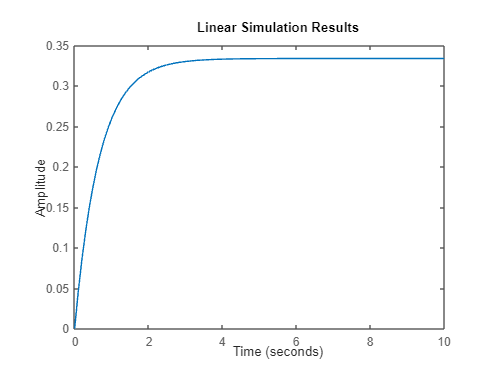


sys_cl = ss(A-B*K,B,C,D);
lsim(sys_cl,u,t,x0);
axis([0 10 0 0.35])

## Calculando el factor de escala para entradas de referencia diferentes de cero

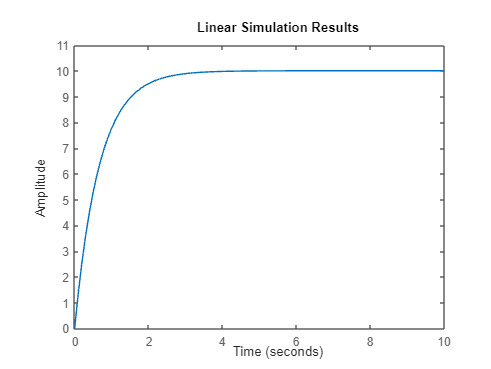

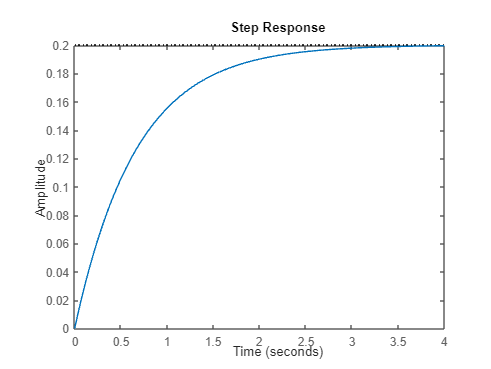

Nbar = rscale(sys,K)*10/500;
sys_cl = ss(A-B*K,B*Nbar,C,D);

lsim(sys_cl,u,t,x0);
axis([0 10 0 11])